简单的雷达回波仿真

雷达发射一个点 信号 然后对目标计算距离和速度

clear;clc;

PRT = 100e-6;                               % 雷达脉冲重复周期
PRF = 1/PRT;                                % 脉冲重复频率
fc = 10e9;                                  % 射频频率
c = 3e8;                                    % 光速
lambda = c/fc;                              % 波长

fs = 20e6;                                  

sig = zeros(round(fs*PRT),1);               %发射波形
sig(1) = 1;                                 %发射波形

r_p = [0;0;0];                              %雷达坐标
t_p = [10000;0;0];                           %目标空间坐标
R = norm(t_p-r_p);                          %雷达到目标的径向距离

Nsweep = 128;                               %发射128个PRT

xr = zeros(round(fs*PRT),Nsweep);           %接收数据缓冲区

参数说明

round(2*R/c/(1/fs));                         %这是信号回波的延迟点数
circshift(sig,round(2*R/c/(1/fs)));          %这是真的回波信号位置
% exp(1j*R/lambda*2*pi)

回波仿真开始

%----------------------------------------------------------------
%   信号回波仿真
%----------------------------------------------------------------
t_v = [-75;0;0];


for idx = 1:Nsweep
    t_p = t_p+t_v*PRT;                          %每个PRT微小位移
    R = norm(t_p-r_p);                          %雷达到目标的径向距离
    
    xr(:,idx) = circshift(sig,round(2*R/c/(1/fs)))...             %目标的距离产生的影响
                .*exp(1j*2*R/lambda*2*pi);                        %目标速度产生的影响
end

xr = xr(2:end,:);                          %剔除发射部分

雷达信号处理

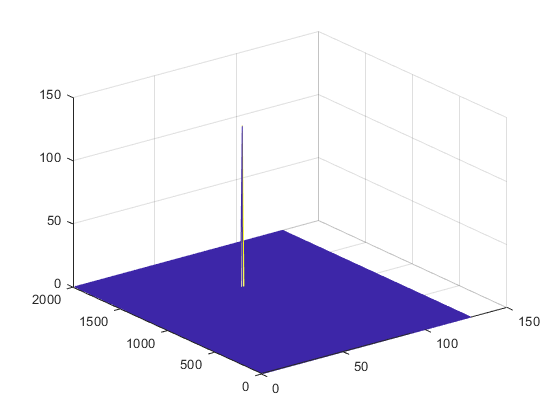

rv = fft(xr,128,2);
mesh(abs(rv));

[X,Y]=find(rv==max(rv(:)));
% 构造查询坐标系
delta_R = (1/fs)*c/2;
X.*delta_R

ans =                     9997.5


vmax = PRF*lambda/2/2;
V = fftshift(linspace(-vmax,+vmax,Nsweep));
disp("距离 m")

距离 m


X.*delta_R

ans =                     9997.5


disp("速度 m/s")

速度 m/s


V(Y)

ans =    -75
